# Example 2: Single Target Monostatic Radar Ranging

Add necessary paths

addpath(genpath("./"))

Assuming a single point target with reflectivity $\sigma_0$ located at $\mathbf{p}_t = [x \ y \ z]$ and antenna element at $\mathbf{p}_a = [x' \ y' \ z']$ 

sigma0 = 1;
pt = [0 0 5]; % Coordinates of the target

pa = [0 0 0]; % Coordinates of the antenna

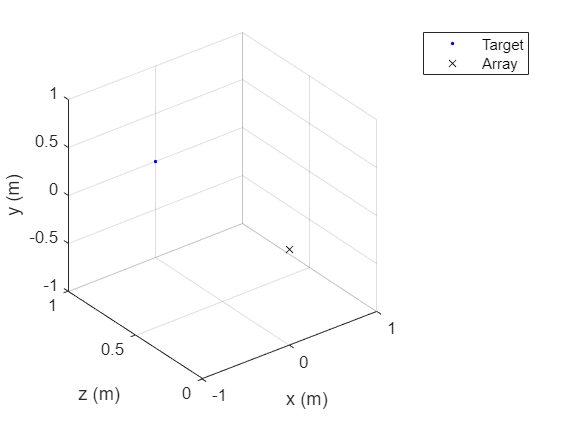

showScenario(pt,pa)

The radar beat signal can be expressed as


$$s(k) = \frac{\sigma_0}{R_0^2} e^{j2kR_0}$$
 

where


$$R_0 = |\mathbf{p}_t - \mathbf{p}_a|_2 = \sqrt{(x-x')^2 + (y-y')^2 + (z-z')^2}$$



$$k = \frac{2 \pi f}{c}, f = f_0 + K t$$


R0 = sqrt(sum((pt - pa).^2,2));

Using the radar parameters from example 1

T = 100e-6;     % T = 100 us 
B = 4e9;        % B = 4 GHz
K = B/T;        % K = 4e13 Hz/s
f0 = 77e9;      % f0 = 77 GHz
Nk = 512;       % 512 ADC samples
fS = Nk/T;      % Sampling rate
c = 299792458;  % Speed of light in m/s

t = (0:Nk-1)/fS;
f = f0 + K*t;
k = 2*pi*f/c;

The beat signal, $s(k)$, can be simulated as

sk = sigma0/R0^2 * exp(1j*2*k*R0);

Taking the FFT of $s(k)$ yields what is known as the range FFT with a peak corresponding to the range of the target

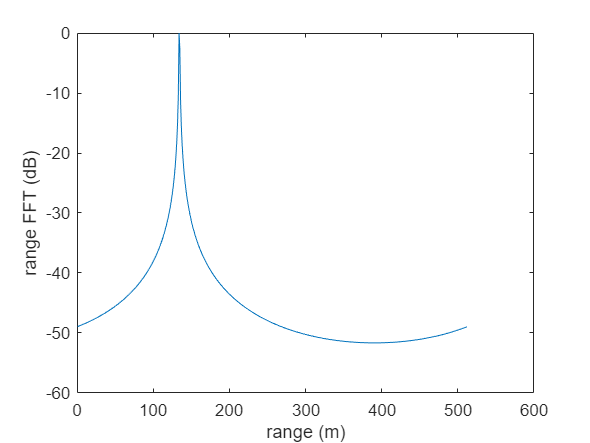

S = fft(sk);

plot(db(abs(S/max(S))))
xlabel("range (m)")
ylabel("range FFT (dB)")

Let's scale the $x$-axis to better understand the data using the maximum resolvable range


$$r_{max} = \frac{f_S c}{2 K}$$


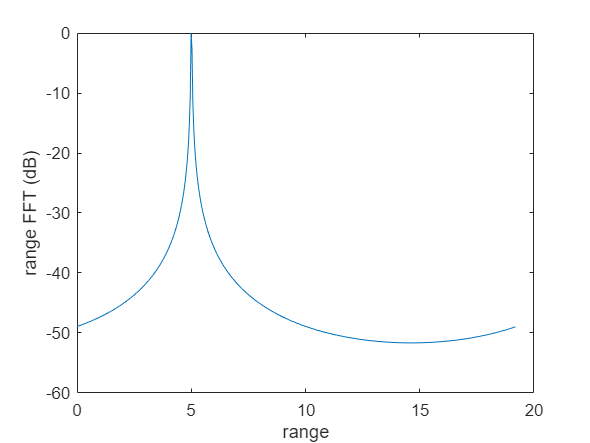

r_max = fS*c/(2*K);
range_axis_m = linspace(0,r_max,length(S));

plot(range_axis_m,db(abs(S/max(S))))
xlabel("range")
ylabel("range FFT (dB)")